# Evaluating contrast and material choice

I intend to compute a simulation of how the light will behave in a lense condition, find the contrast between the material and vacuum regions, and plot contrast vs thickness on a 2-D graph.

I am writing a program that I will call in this script. I'm going to use my data from yesterday for this mask, but with only Ru:

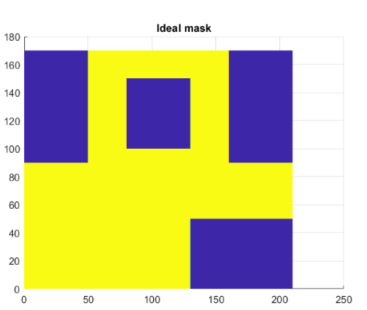

[A,B] = SimulateGrating(Material,Thickness_range,GratingSize,RectangleLocation, RectangleArea,z_elevation,NA)

The script as I've written it doesn't handle composites quite yet.

Edit 1: adding a thickness slider for SIM called default_thick

Edit 2: Nevermind, I dont want to change how Ive written it to make that work

%mpm addpath; % set local path to include dependencies
Material='Ru';

step=0.001;
Thickness_range=[3:step:13];
%default_thick=12.5;
width=210;
height=170;
GratingSize=[width,height];
%location:
loc_tl=[25,height-40];
loc_tr=[width-25,height-40];
loc_br=[width-40,25];
loc_mid=[width/2,125];
RectangleLocation=[loc_tl;loc_tr;loc_br;loc_mid];
%Area
sz_tl=[50,80];
sz_tr=[50,80];
sz_br=[80,50];
sz_mid=[50,50];
RectangleArea=[sz_tl;sz_tr;sz_br;sz_mid];
z_elevation=0;
%Aperture
NA=0.05;
%light doping thresold
threshold=0.4;


Now to try it

[A,B]=SimulateGrating(Material,Thickness_range,GratingSize,RectangleLocation, RectangleArea,z_elevation,NA,threshold);
A